%Ecuaciones diferenciales
clc
clear
f0=sym(0.5*(60*60*24*365))

$$f0 = 15768000$$

V1=sym(1.8965e+10) %Great Salt lake

$$V1 = 18965000000$$

V2=sym(1.7500e+09) %Bear

$$V2 = 1750000000$$

X0=sym([170;0]) %Condiciones iniciales

$$X0 = \left(\begin{array}{c} 170\\ 0 \end{array}\right)$$


syms t
n=2

n = 2

A=([-f0/V1 0;f0/V2 -f0/V2])

$$A = \left(\begin{array}{cc} -\frac{1971}{2370625} & 0\\ \frac{1971}{218750} & -\frac{1971}{218750} \end{array}\right)$$

%A=[1 2;4 3]
[P,D]=eig(A)

$$P = \left(\begin{array}{cc} 0 & \frac{3443}{3793}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} -\frac{1971}{218750} & 0\\ 0 & -\frac{1971}{2370625} \end{array}\right)$$

P_INV=inv(P);
for i=1:n
    for j=1:n
        if i==j
    DT(i,j)=sym(exp(D(i,j)*t));
        else
      DT(i,j)=0; 
        end
    end
end
DT

$$DT = \left(\begin{array}{cc} {\mathrm{e}}^{-\frac{1971\,t}{218750}} & 0\\ 0 & {\mathrm{e}}^{-\frac{1971\,t}{2370625}} \end{array}\right)$$

X=P*DT*P_INV*X0%,5)

$$X = \left(\begin{array}{c} 170\,{\mathrm{e}}^{-\frac{1971\,t}{2370625}}\\ \frac{644810\,{\mathrm{e}}^{-\frac{1971\,t}{2370625}}}{3443}-\frac{644810\,{\mathrm{e}}^{-\frac{1971\,t}{218750}}}{3443} \end{array}\right)$$

 
syms t f1(t) g1(t)
f1(t)=X(1)

$$f1(t) = 170\,{\mathrm{e}}^{-\frac{1971\,t}{2370625}}$$

g1(t)=X(2)

$$g1(t) = \frac{644810\,{\mathrm{e}}^{-\frac{1971\,t}{2370625}}}{3443}-\frac{644810\,{\mathrm{e}}^{-\frac{1971\,t}{218750}}}{3443}$$


g2(t)=diff(g1,t)

$$g2(t) = \frac{127092051\,{\mathrm{e}}^{-\frac{1971\,t}{218750}}}{75315625}-\frac{67014\,{\mathrm{e}}^{-\frac{1971\,t}{2370625}}}{430375}$$

tt=solve(vpa(g1==5),t,"Real",true)

$$tt = 3.3178735067954831705183678496671$$

p=solve(g2==0,t)

$$p = \frac{829718750\,\log\left(\frac{3793}{350}\right)}{6786153}$$


vpa(t,7)%Tiempo de concentracion maxima

$$ans = t$$

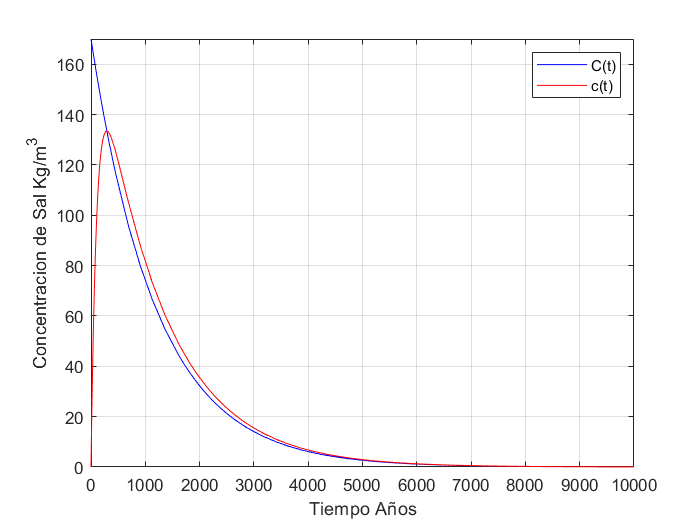

fplot(f1,[0 10000],'b')
xlabel("Tiempo Años")
ylabel("Concentracion de Sal Kg/m^3")
hold on
grid on
fplot(g1,[0 10000],'r')
legend('C(t)','c(t)')